# Azure to Matlab

% Set the Azure Blob Storage information
storageAccountName = 'historicalpower';
storageContainerName = 'data';
blobName = 'data.xlsx';

SASToken = "sp=r&st=2023-10-30T16:16:14Z&se=2023-10-31T00:16:14Z&spr=https&sv=2022-11-02&sr=b&sig=EAbAKC4dCCO74TBeK4ywiVaYE9Vv%2F32XdC2a4aGT%2B%2Fg%3D";
setenv("MW_WASB_SAS_TOKEN",SASToken);

URL = "wasbs://data@historicalpower.blob.core.windows.net/data.xlsx";

data=datastore(URL)

data =   SpreadsheetDatastore with properties:

                      Files: {
                             'wasbs://data@historicalpower.blob.core.windows.net/data.xlsx'
                             }
                    Folders: {
                             'wasbs://data@historicalpower.blob.core.windows.net'
                             }
   AlternateFileSystemRoots: {}
                     Sheets: ''
                      Range: ''

  Sheet Format Properties:
             NumHeaderLines: 0
         VariableNamingRule: 'modify'
          ReadVariableNames: true
              VariableNames: {'x_2005_07_0100_00_00_0__', 'x13981'}
              VariableTypes: {'char', 'double'}

  Properties that control the table returned by preview, <a href="matlab: help('matlab.io.datastore.SpreadsheetDatastore\read')">read<


Data=read(data)

Data = 8759x2 table
     x_2005_07_0100_00_00_0__      x13981
    ___________________________    ______

    {''2005-07-01 00:00:00.0''}    13162 
    {''2005-07-01 00:00:00.0''}    12699 
    {''2005-07-01 00:00:00.0''}    12464 
    {''2005-07-01 00:00:00.0''}    12599 
    {''2005-07-01 00:00:00.0''}    13242 
    {''2005-07-01 00:00:00.0''}    14740 
    {''2005-07-01 00:00:00.0''}    16502 
    {''2005-07-01 00:00:00.0''}    17689 
    {''2005-07-01 00:00:00.0''}    18548 
    {''2005-07-01 00:00:00.0''}    19188 
    {''2005-07-01 00:00:00.0''}    19599 
    {''2005-07-01 00:00:00.0''}    19763 
    {''2005-07-01 00:00:00.0''}    19972 
    {''2005-07-01 00:00:00.0''}    20037 
    {''2005-07-01 00:00:00.0''}    20018 
    {''2005-07-01 00:00:00.0''}    19937 


%%Data2=readtable("/MATLAB Drive/BTP/data.xlsx")

# Data Processing

% Assuming your data is stored in a variable named 'Data'

% Step 1: Preprocess the data
time = Data(:, 1); % Extract time column
power_consumption = Data(:, 2); % Extract power consumption column

% Perform the normalization once the data type is numeric
normalized_power = (power_consumption - mean(power_consumption))

normalized_power = 8759x1 table
    x13981 
    _______

    -2222.8
    -2685.8
    -2920.8
    -2785.8
    -2142.8
    -644.85
     1117.2
     2304.2
     3163.2
     3803.2
     4214.2
     4378.2
     4587.2
     4652.2
     4633.2
     4552.2



normalized_power=(normalized_power)./ max(normalized_power)

normalized_power = 8759x1 table
     x13981  
    _________

     -0.19329
     -0.23355
     -0.25398
     -0.24224
     -0.18633
    -0.056073
     0.097142
      0.20036
      0.27505
       0.3307
      0.36644
       0.3807
      0.39888
      0.40453
      0.40288
      0.39583


% Convert normalized_power table to an array
normalized_power_array = table2array(normalized_power)

% Define the time step for creating sequences
time_step = 24;

% Generate sequences from the normalized data
data_train = [];
for i = 1:size(normalized_power_array, 1) - time_step
    data_train = [data_train; normalized_power_array(i:i+time_step-1)'];
end


data_train

%data_train=table2array(data_train)
XTrain = data_train(1:end, :) % Use all but the last 24 sequences for training
YTrain = normalized_power_array(time_step+1:end) % The target for each training sequence is the next value in the time series

# Model Training

layers = [ ...
    sequenceInputLayer(time_step) % Define the input layer
    lstmLayer(250) % Define the LSTM layer
    fullyConnectedLayer(1) % Define the fully connected layer
    regressionLayer]; % Define the regression layer

options = trainingOptions('adam', 'MaxEpochs', 250);
net = trainNetwork(XTrain', YTrain', layers, options);

Training on single CPU.
|========================================================================================|
|  Epoch  |  Iteration  |  Time Elapsed  |  Mini-batch  |  Mini-batch  |  Base Learning  |
|         |             |   (hh:mm:ss)   |     RMSE     |     Loss     |      Rate       |
|========================================================================================|
|       1 |           1 |       00:00:00 |         0.32 |      5.1e-02 |          0.0010 |
|      50 |          50 |       00:00:49 |         0.06 |      1.9e-03 |          0.0010 |
|     100 |         100 |       00:01:40 |         0.05 |      1.3e-03 |          0.0010 |
|     150 |         150 |       00:02:28 |         0.04 |      1.0e-03 |          0.0010 |
|     200 |         200 |       00:03:20 |         0.04 |      9.7e-04 |          0.0010 |
|     250 |         250 |       00:04:10 |         0.04 |      7.6e-04 |          0.0010 |
|=================================================================


% Save the trained network
save('model.mat', 'net');

% Clear the current workspace
%clear net;


# Load saved model

% Save the trained network
%save('model.mat', 'net');

% Load the saved network back into the workspace
loaded_net = load('model.mat');
net = loaded_net.net

# prediction using model

XForecast = data_train(end-time_step+1:end, :); % Use the last 24 sequences for forecasting
YPred = predict(net, XForecast')

# forcasting on normalized power data


% Visualize the results for the last 24 values
last_index = size(normalized_power_array, 1)

last_index = 8759

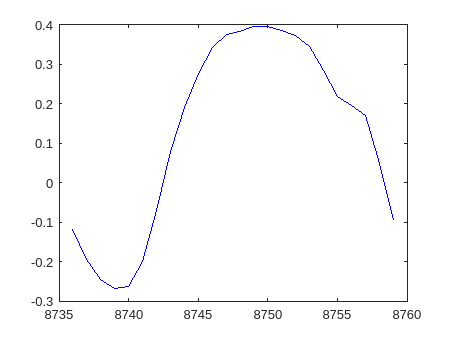


figure;
plot(last_index-23:last_index, normalized_power_array(last_index-23:last_index), 'b'); % Plot the last 24 values of the normalized data
hold on

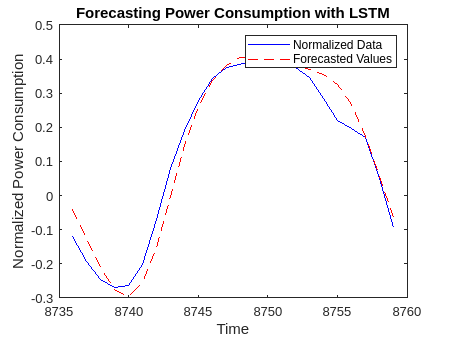


% Plot the forecasted values
time_forecast = last_index-23:last_index; % Assuming YPred is a 1x24 vector
plot(time_forecast,  YPred, 'r--'); % Plot the forecasted values

% Add labels and title
legend('Normalized Data', 'Forecasted Values');
xlabel('Time');
ylabel('Normalized Power Consumption');
title('Forecasting Power Consumption with LSTM');

# forcasting on original data

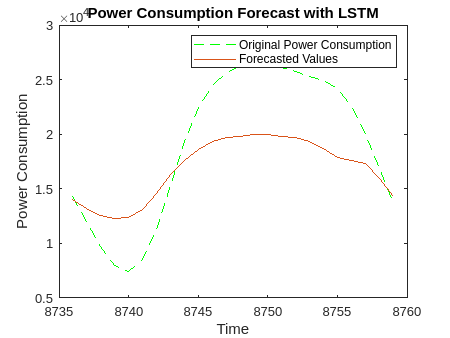

figure;
power_consumption_array = table2array(power_consumption);
max_power = max(power_consumption_array);
mean_power = mean(power_consumption_array);

YPred_original_scale = YPred * max_power + mean_power

% Plot the forecasted values in the original power consumption scale
time_forecast = last_index-23:last_index; % Assuming YPred is a 1x24 vector
plot(time_forecast, YPred_original_scale, 'g--'); % Plot the forecasted values

hold on
plot(time_forecast,power_consumption_array(last_index-23:last_index))

% Add labels and title
legend('Original Power Consumption', 'Forecasted Values');
xlabel('Time');
ylabel('Power Consumption');
title('Power Consumption Forecast with LSTM');

# forcasting on unknown 24 hours data



% Assuming net is the trained LSTM model
num_forecast_hours = 24;  % Number of hours to forecast

% Use the last 'time_step' hours as initial input for forecasting
XForecast = normalized_power_array(end-time_step+1:end)';

% Initialize an array to store forecasted values
YPredo = zeros(1, num_forecast_hours);

% Forecast the next 24 hours
for i = 1:num_forecast_hours
    % Predict the next value
    YPredo(i) = predict(net, XForecast');
    
    % Update XForecast with the new value for the next iteration
    XForecast = [XForecast(2:end), YPredo(i)];
end


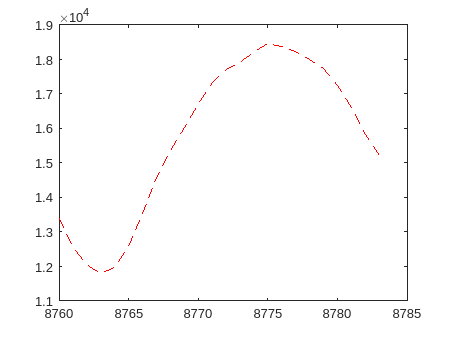


figure;
power_consumption_array = table2array(power_consumption);
max_power = max(power_consumption_array);
mean_power = mean(power_consumption_array);
YPred_original_scale = YPredo * max_power + mean_power;

% Plot the forecasted values in the original power consumption scale
time_forecast = last_index+1:last_index+num_forecast_hours; % Assuming YPred is a 1x24 vector
plot(time_forecast, YPred_original_scale, 'r--'); % Plot the forecasted values

save YPred_original_scale

load YPred_original_scale.mat

% Read the true values from the Excel file
true_values_table = readtable('/MATLAB Drive/BTP/valdata.xlsx');
true_values = table2array(true_values_table(:,2))


hold on;
plot(time_forecast, true_values, 'b'); % Plot the true values
legend('Original Power Consumption', 'True Values');

% Add labels and title
legend('Forecasted Values','Original Power Consumption');
xlabel('Time');
ylabel('Power Consumption');
title('Power Consumption Forecast with LSTM');

# Connectivity of opcua

serverList =  opcuaserverinfo('opc.tcp://DESKTOP-HIK2EG1:53530/OPCUA/SimulationServer')

serverList = OPC UA ServerInfo 'SimulationServer@DESKTOP-HIK2EG1':

   Connection Information:
               Hostname: 'DESKTOP-HIK2EG1'
                   Port: 53530
              Endpoints: [1×11 opc.ua.EndpointDescription]

   Security Information:
    BestMessageSecurity: SignAndEncrypt
    BestChannelSecurity: Aes256_Sha256_RsaPss
         UserTokenTypes: {'Anonymous'  'Username'  'Certificate'}


sampleServerInfo = findDescription(serverList, 'Simulation')

sampleServerInfo = OPC UA ServerInfo 'SimulationServer@DESKTOP-HIK2EG1':

   Connection Information:
               Hostname: 'DESKTOP-HIK2EG1'
                   Port: 53530
              Endpoints: [1×11 opc.ua.EndpointDescription]

   Security Information:
    BestMessageSecurity: SignAndEncrypt
    BestChannelSecurity: Aes256_Sha256_RsaPss
         UserTokenTypes: {'Anonymous'  'Username'  'Certificate'}


uaClient = opcua(sampleServerInfo)

uaClient = OPC UA Client:

   Server Information:
                     Name: 'SimulationServer@DESKTOP-HIK2EG1'
                 Hostname: 'DESKTOP-HIK2EG1'
                     Port: 53530
              EndpointUrl: 'opc.tcp://DESKTOP-HIK2EG1:53530/OPCUA/SimulationServer'

   Connection Information:
                  Timeout: 10
                   Status: 'Disconnected'
              ServerState: '<Not connected>'

   Security Information:
      MessageSecurityMode: SignAndEncrypt
    ChannelSecurityPolicy: Aes256_Sha256_RsaPss
                Endpoints: [1×11 opc.ua.EndpointDescription]


status = uaClient.Status

status = 'Disconnected'

isConnected(uaClient)

ans = logical
   0


connect(uaClient)
uaClient

uaClient = OPC UA Client:

   Server Information:
                       Name: 'SimulationServer@DESKTOP-HIK2EG1'
                   Hostname: 'DESKTOP-HIK2EG1'
                       Port: 53530
                EndpointUrl: 'opc.tcp://DESKTOP-HIK2EG1:53530/OPCUA/SimulationServer'

   Connection Information:
                    Timeout: 10
                     Status: 'Connected'
                ServerState: 'Running'

   Security Information:
        MessageSecurityMode: SignAndEncrypt
      ChannelSecurityPolicy: Aes256_Sha256_RsaPss
                  Endpoints: [1×11 opc.ua.EndpointDescription]

   Server Limits:
              MinSampleRate: 0 sec
               MaxReadNodes: 0
              MaxWriteNodes: 0
        MaxHistoryReadNodes: 0
    MaxHistoryValuesPerNode: 0


uaClient = opcua('localhost', 53530);
connect(uaClient);


tempVariable1 = findNodeByName(uaClient.Namespace, 'request', '-once');
tempVariable2 = findNodeByName(uaClient.Namespace, 'forcest', '-once');
tempvariable3 = findNodeByName(uaClient.Namespace, 'data', '-once');

while true  
    
    [value, timestamp, quality] = readValue(uaClient, tempVariable1)
    if value == 17
%         data=datastore(URL)
%         % Load the saved network back into the workspace
%         loaded_net = load('trained_net.mat');
%         net = loaded_net.net;
%         load YPred_original_scale.mat
        
        for t=1:24
            newValue1 = YPred_original_scale(t);
            newValue2 = true_values(t);
            writeValue(uaClient, tempVariable2, newValue1);
            writeValue(uaClient, tempvariable3, newValue2);
            pause(1);
        end
        break;  % Breaking the loop
    end
    pause(0.1);  % Adjust the pause duration as needed
end

value = int8
0

timestamp = datetime
   31-Oct-2023 00:15:20


quality = OPC UA Quality ID:
	Good

value = int8
0

timestamp = datetime
   31-Oct-2023 00:15:21


quality = OPC UA Quality ID:
	Good

value = int8
0

timestamp = datetime
   31-Oct-2023 00:15:21


quality = OPC UA Quality ID:
	Good

value = int8
0

timestamp = datetime
   31-Oct-2023 00:15:21


quality = OPC UA Quality ID:
	Good

value = int8
0

timestamp = datetime
   31-Oct-2023 00:15:21


quality = OPC UA Quality ID:
	Good

value = int8
0

timestamp = datetime
   31-Oct-2023 00:15:21


quality = OPC UA Quality ID:
	Good

value = int8
0

timestamp = datetime
   31-Oct-2023 00:15:21


quality = OPC UA Quality ID:
	Good

value = int8
0

timestamp = datetime
   31-Oct-2023 00:15:22


quality = OPC UA Quality ID:
	Good

value = int8
0

timestamp = datetime
   31-Oct-2023 00:15:22


quality = OPC UA Quality ID:
	Good

value = int8
0

timestamp = datetime
   31-Oct-2023 00:15:22


quality = OPC UA Quality ID:
	Good

value = int8
0

timestamp = datetime
   31-Oct-2023 00:15:22


quality = OPC UA Quality ID:
	Good

value = int8
0

timestamp = datetime
   31-Oct-2023 00:15:23


quality = OPC UA Quality ID:
	Good

value = int8
0

timestamp = datetime
   31-Oct-2023 00:15:23


quality = OPC UA Quality ID:
	Good

value = int8
0

timestamp = datetime
   31-Oct-2023 00:15:23


quality = OPC UA Quality ID:
	Good

value = int8
0

timestamp = datetime
   31-Oct-2023 00:15:24


quality = OPC UA Quality ID:
	Good

value = int8
0

timestamp = datetime
   31-Oct-2023 00:15:24


quality = OPC UA Quality ID:
	Good

value = int8
0

timestamp = datetime
   31-Oct-2023 00:15:24


quality = OPC UA Quality ID:
	Good

value = int8
0

timestamp = datetime
   31-Oct-2023 00:15:25


quality = OPC UA Quality ID:
	Good

value = int8
0

timestamp = datetime
   31-Oct-2023 00:15:25


quality = OPC UA Quality ID:
	Good

value = int8
0

timestamp = datetime
   31-Oct-2023 00:15:26


quality = OPC UA Quality ID:
	Good

value = int8
0

timestamp = datetime
   31-Oct-2023 00:15:26


quality = OPC UA Quality ID:
	Good

value = int8
0

timestamp = datetime
   31-Oct-2023 00:15:26


quality = OPC UA Quality ID:
	Good

value = int8
0

timestamp = datetime
   31-Oct-2023 00:15:26


quality = OPC UA Quality ID:
	Good

value = int8
0

timestamp = datetime
   31-Oct-2023 00:15:26


quality = OPC UA Quality ID:
	Good

value = int8
0

timestamp = datetime
   31-Oct-2023 00:15:26


quality = OPC UA Quality ID:
	Good

value = int8
0

timestamp = datetime
   31-Oct-2023 00:15:27


quality = OPC UA Quality ID:
	Good

value = int8
0

timestamp = datetime
   31-Oct-2023 00:15:27


quality = OPC UA Quality ID:
	Good

value = int8
0

timestamp = datetime
   31-Oct-2023 00:15:27


quality = OPC UA Quality ID:
	Good

value = int8
0

timestamp = datetime
   31-Oct-2023 00:15:27


quality = OPC UA Quality ID:
	Good

value = int8
0

timestamp = datetime
   31-Oct-2023 00:15:27


quality = OPC UA Quality ID:
	Good

value = int8
0

timestamp = datetime
   31-Oct-2023 00:15:28


quality = OPC UA Quality ID:
	Good

value = int8
0

timestamp = datetime
   31-Oct-2023 00:15:28


quality = OPC UA Quality ID:
	Good

value = int8
0

timestamp = datetime
   31-Oct-2023 00:15:28


quality = OPC UA Quality ID:
	Good

value = int8
0

timestamp = datetime
   31-Oct-2023 00:15:28


quality = OPC UA Quality ID:
	Good

value = int8
0

timestamp = datetime
   31-Oct-2023 00:15:28


quality = OPC UA Quality ID:
	Good

value = int8
0

timestamp = datetime
   31-Oct-2023 00:15:28


quality = OPC UA Quality ID:
	Good

value = int8
0

timestamp = datetime
   31-Oct-2023 00:15:29


quality = OPC UA Quality ID:
	Good

value = int8
0

timestamp = datetime
   31-Oct-2023 00:15:29


quality = OPC UA Quality ID:
	Good

value = int8
17

timestamp = datetime
   31-Oct-2023 00:15:29


quality = OPC UA Quality ID:
	Good

YPred_original_scale(6)